# Exercício 3

## Usando a Transformação Bilinear projete filtros digitais passa-altas de Butterworth, Chebyshev e Elíptico que satisfaçam as seguintes especificações:


$$\\
A_{p} = 1 [dB]\\
A_{r} = 40 [dB]\\
\Omega_{r} = 5912.5 [rad/s]\\
\Omega_{p} = 7539.8 [rad/s]\\
\Omega_{a} = 50265.5 [rad/s]
$$


## Esboce as curvas de resposta em frequência de cada um desses filtros. Comente adequadamente os resultados obtidos.

## DICA: Use as fuções do MatLab.

Assim como nos exercícios anteriores, vamos iniciar instanciando as variáveis utilizadas como parâmetros do filtro:

% Parâmetros 
A_p     =  1; % dB
A_r     =  40; % dB
Omega_r =   5912.5; % rad/s
Omega_p =   7539.8; % rad/s
Omega_a  = 50265.5; % rad/s freq. angular de amostragem

% Normalização dos parâmetros
K = (2*pi)/Omega_a;

w_p = Omega_p*K;
w_r = Omega_r*K;
dw = w_r-w_p; % banda de transição
w_c = w_r+dw/2; % frequência de corte a ser utilizada nos filtros

Todavia, diferentemente das vezes anteriores, implementaremos filtros IIR ao invés de filtros FIR.

Iniciando pelo filtro Butterworth, temos que primeiro calcular os parâmetros de ordem do filtro:

[n, Wn] = buttord(w_p/pi, w_r/pi, A_p, A_r)

n = 20

Wn = 0.2888

[b, a] = butter(n,Wn, 'high');
[H_butt, omega_butt] = freqz(b, a);
mag_butt = 20*log10(abs(H_butt));

Repetindo o processo para o filtro de Chebyshev, temos:

[n, Wn] = cheb1ord(w_p/pi, w_r/pi, A_p, A_r)

n = 8

Wn = 0.3000

[b, a] = cheby1(n, A_p, Wn, 'high');
[H_cheby, omega_cheby] = freqz(b, a);
mag_cheby = 20*log10(abs(H_cheby));

Agora para o filtro elíptico:

[n,Wp] = ellipord(w_p/pi, w_r/pi, A_p, A_r)

n = 5

Wp = 0.3000

[b, a] = ellip(n, A_p, A_r, Wp, 'high');
[H_ellip, omega_ellip] = freqz(b, a);
mag_ellip = 20*log10(abs(H_ellip));

Comparando a performance do módulo da resposta e da fase desses filtros, temos o seguinte gráfico:

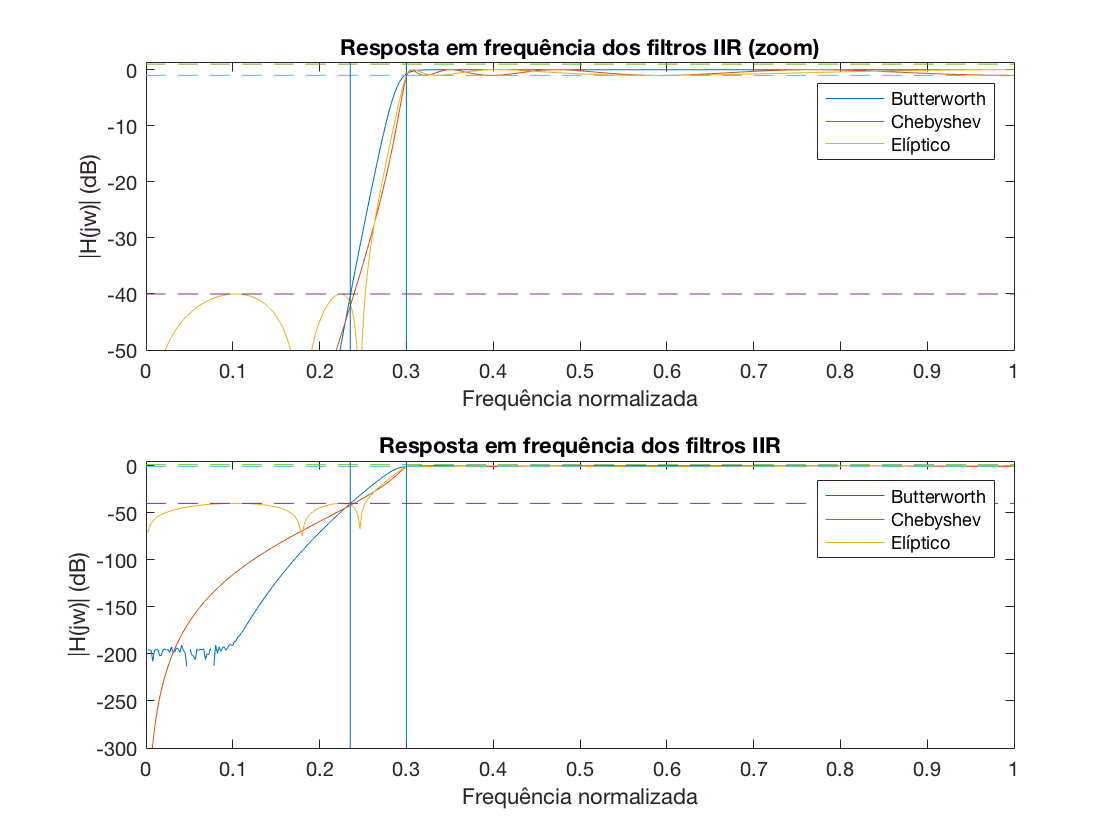

w = linspace(0,1,512);

spec40db = -A_r*ones(512);
specup1db = A_p*ones(512);
specdown1db = -A_p*ones(512);

figure(1)
subplot(2,1,1); grid
plot(w, mag_butt, 'DisplayName','Butterworth')
hold on
plot(w, mag_cheby,'DisplayName','Chebyshev')
plot(w, mag_ellip, 'DisplayName','Elíptico')
legend('show')
plot(w, spec40db, '--', w, specup1db,'--', w, specdown1db, '--')
ylim([-50 1.2]) % mostrando no mínimo -50 dB para melhorar o zoom
line([w_p/pi w_p/pi], ylim)
line([w_r/pi w_r/pi], ylim)
title('Resposta em frequência dos filtros IIR (zoom)')
ylabel('|H(jw)| (dB)')
xlabel('Frequência normalizada')
hold off
subplot(2,1,2); grid
plot(w, mag_butt, 'DisplayName','Butterworth')
hold on
plot(w, mag_cheby,'DisplayName','Chebyshev')
plot(w, mag_ellip, 'DisplayName','Elíptico')
legend('show')
plot(w, spec40db, '--', w, specup1db,'--', w, specdown1db, '--')
ylim([-300 5]) % zoom out
line([w_p/pi w_p/pi], ylim)
line([w_r/pi w_r/pi], ylim)
title('Resposta em frequência dos filtros IIR')
ylabel('|H(jw)| (dB)')
xlabel('Frequência normalizada')
hold off

Os resultados acima nos mostram que todos os filtros ficaram dentro da especificação, como esperado.

Aqui também podemos observar as diferentes características de cada um dos filtros em ação, como por exemplo:

- O filtro Butterworth oferece a melhor aproximação da série de Taylor de um filtro passa-altas ideal, e por isso acaba apresentando uma resposta em geral monotônica e quase constante em boa parte das faixas de passagem e rejeição do filtro. Sua performance, todavia, vem ao custo de ser o filtro de maior ordem entre os três (20);

- O filtro Chebyshev de tipo 1 aqui utilizado minimiza a diferença entre um passa-altas ideal e o obtido. Ele acaba apresentando uma banda de transição mais abrupta que a do Butterworth mas uma atenuação menor na banda de rejeição. Esse filtro se apresenta como o melhor trade-off entre ordem (8) e performance.

- O filtro Elípitico é *equiripple* na banda de passagem e de rejeição. Isso permite que ele tenha a menor ordem de todos os filtros (5) mas a pior performance tanto na banda de passagem quanto na banda de rejeição.